# Linear Control Design II - Group Work Problem Module 12

## Description

**Problems**

The assignment deals with the multi-variable controller design for the TITO (two-inputs two-outputs) model of the aircraft introduced in Group Work Module 9.

The state space representation of the model is


$$ \pmatrix
    { \dot{\beta}\cr
   \dot{r}\cr
   \dot{p}\cr
   \dot{\phi}}
 =    \left(\begin{array}{cccc} -0.0558 & -0.9968 & 0.0802 & 0.0415\\ 0.598 & -0.115 & -0.0318 & 0\\ -3.05 & 0.388 & -0.465 & 0\\ 0 & 0.0805 & 1.0 & 0 \end{array}\right)
 \pmatrix{
   \beta \cr
   r\cr
   p\cr
   \phi}
 
 +
\left(\begin{array}{cc} 0.00729 & 0.00001\\ -0.475 & 0.123\\ 0.153 & 1.063\\ 0 & 0 \end{array}\right)
 \pmatrix{
   \delta r\cr
   \delta a
  } \\
 \mathbf{y}=\pmatrix{
  0 \ 1 \ 0 \ 0\cr
  0 \ 0 \ 0 \ 1
 }
 \pmatrix{  \beta\cr
   r\cr
   p\cr
   \phi
  }$$


**Problem 1** 	Assess if the open loop system is controllable. Is the system stabilizable?.

**Solution****:**

% Your solution goes here: 
A=[-.0558 -.9968 .0802 .0415;
   .598 -.115 -.0318 0;
   -3.05 .388 -.4650 0;
   0 .0805 1 0];
B=[.0729  .0001;
   -4.75   1.23;
   1.53   10.63;
   0      0]/10;
C=[0 1 0 0;
   0 0 0 1];
D=[0 0;
   0 0];
Mc = ctrb(A,B)

Mc =       0.00729        1e-05      0.48534    -0.037354    -0.098535     0.058581     -0.40443    0.0049517
       -0.475        0.123     0.054119    -0.047942      0.29284   -0.0026226    -0.050301     0.025698
        0.153        1.063     -0.27768      -0.4466      -1.3302        0.303       1.0327     -0.32059
            0            0      0.11476       1.0729     -0.27332     -0.45046      -1.3066      0.30279


%Test Controlabilityt
[rank(Mc), size(A,1)]

ans =      4     4


**Problem 2** A multi-variable full state feedback controller $\mathbf{u} = -\mathbf{K}\mathbf{x} + \mathbf{r}$ for the aircraft is to be designed. The continuous time closed-loop system's eigenvalues have to be placed at the following location in the left half plane


$$ \lambda=\left\{\begin{array}{l}
	  -0.5\\ -0.6\\ -0.5\pm 0.5\rm{j}
	 \end{array}$$


Design a discrete time controller and use the sampling period ${0.1}$$s$. Find the gain matrix $\mathbf{K}$ for the controller by applying the Matlab function *place*. Check the position of the eigenvalues of the closed-loop system. Are the design requirements fulfilled?

**Solution****:**

% Your solution goes here:
pl = [-.5 -.6 -.5-.5j -.5+.5j];
K = place(A,B,pl)

K =       -1.4256      -1.7645     -0.63117     -0.36287
      -2.3647      0.11052      0.67682      0.31429


E = eig(A-B*K)

E =          -0.5 +        0.5i
         -0.5 -        0.5i
         -0.5 +          0i
         -0.6 +          0i


**Problem 3 ** Add the controller to the Simulink model and carry out a simulation with the function in Figure1 as reference signal for both inputs, but one at a time. Plot the states, outputs and control signals, i.e. the rudder angle and the aileron angle.

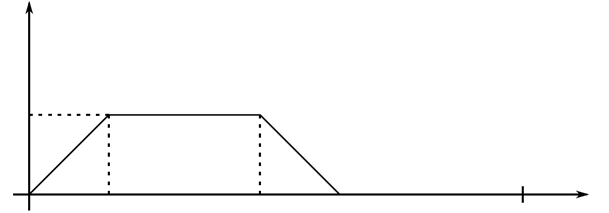

**Solution****:**

% Your solution goes here:




**Problem 4 ** Now suppose that the aircraft's rudder and aileron servos are slower than we thought. Add a $1 \ s$ time constant to each of the continuous control inputs and see what happens. How could the problem be solved?

**Solution****:**

% Your solution goes here:




**Problem 5 **Find the stationary output $\mathbf{y}_0$ for the closed-loop system and for the constant reference inputs $\mathbf{r}(k)=\left[\matrix{0.1 \   0}\right]^\mathrm{T}$ and $\mathbf{r}(k)=\left[\matrix{0  \ 0.1}\right]^\mathrm{T}$. Does $y_0$ depend on the eigenvalue placement? (`Hint: For a stationary state the discrete state vector is constant, i.e.` $\mathbf{x}(k+1)=\mathbf{x}(k)$).

**Solution****:**

% Your solution goes here:


